clear all;
close all;
clc;

Wp = tf(10, conv(conv([5 1], [4 1]), [2 1]));
pole(Wp)

ans =    -0.5000
   -0.2500
   -0.2000


dcgain(Wp)

ans = 10

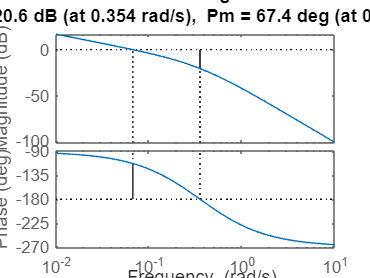

%Ap*(1 + 1/(Ti*s))
%(Ap*Ti*s + Ap)/(Ti*s)
%(Ap/Ti)*(Ti*s + 1)/(s)
Ap = 0.035;
Ti = 5;
Wc = (Ap/Ti)*tf([Ti 1],[1 0]);
Wo = minreal(Wc*Wp);

margin(Wo)

[Gm Pm wcg wcp] = margin(Wo)

Gm = 10.7143

Pm = 67.3606

wcg = 0.3536

wcp = 0.0670

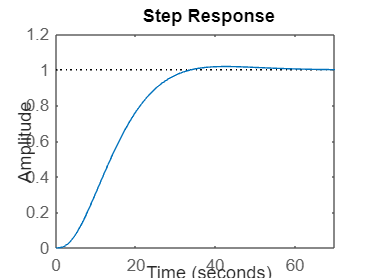


W = feedback(Wo, 1, -1);

step(W)

stepinfo(W)

ans = struct with fields:
         RiseTime: 19.6627
    TransientTime: 31.0488
     SettlingTime: 31.0488
      SettlingMin: 0.9074
      SettlingMax: 1.0180
        Overshoot: 1.8042
       Undershoot: 0
             Peak: 1.0180
         PeakTime: 42.4128


e = 1-dcgain(W)

e = 0


Wru = feedback(Wc, Wp, -1);
stepinfo(Wru)

ans = struct with fields:
         RiseTime: 11.1319
    TransientTime: 39.9224
     SettlingTime: 35.7598
      SettlingMin: 0.0901
      SettlingMax: 0.1034
        Overshoot: 3.4337
       Undershoot: 0
             Peak: 0.1034
         PeakTime: 25.6341



pd = -0.9;
Ts = -deg2rad(2*pd/wcg)

Ts = 0.0889

Wd = c2d(W,Ts,'zoh')

Wd =
 
  1.006e-06 z^2 + 3.959e-06 z + 9.733e-07
  ---------------------------------------
     z^3 - 2.935 z^2 + 2.87 z - 0.9355
 
Sample time: 0.088858 seconds
Discrete-time transfer function.
Model Properties


Wp = tf(0.5, conv(conv([1 0], [1 1]), [4 1]));
pole(Wp)

ans =          0
   -1.0000
   -0.2500


dcgain(Wp)

ans = Inf

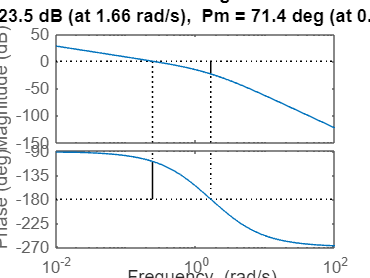

%Ap*(1 + (Td*s)/(Tc*s +1))
%Ap*((Td+Tc)*s + 1)/(Tc*s +1)
%Td+Tc = 4
%Td/Tc = N -> Td = N*Tc
% (N+1)*Tc = 4
Ap = 0.5;
N = 10;
Tc = 4/(N+1);
Td = N*Tc;
Wc = Ap*tf([Td+Tc 1], [Tc 1]);

Wo = minreal(Wc*Wp);
margin(Wo)

[Gm Pm wcg wcp] = margin(Wo)

Gm = 15.0000

Pm = 71.3633

wcg = 1.6583

wcp = 0.2420

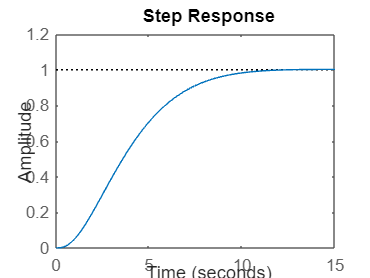


W = feedback(Wo, 1, -1);

step(W)

stepinfo(W)

ans = struct with fields:
         RiseTime: 5.8976
    TransientTime: 9.8389
     SettlingTime: 9.8389
      SettlingMin: 0.9004
      SettlingMax: 1.0019
        Overshoot: 0.1949
       Undershoot: 0
             Peak: 1.0019
         PeakTime: 14.6695


e = 1-dcgain(W)

e = 0


Wru = feedback(Wc, Wp, -1);
stepinfo(Wru)

ans = struct with fields:
         RiseTime: 0
    TransientTime: 2.0495
     SettlingTime: NaN
      SettlingMin: -0.0995
      SettlingMax: 5.5000
        Overshoot: Inf
       Undershoot: Inf
             Peak: 5.5000
         PeakTime: 0



Wde = -feedback(Wp, Wc, -1)

Wde =
 
                 -0.1818 s - 0.5
  ----------------------------------------------
  1.455 s^4 + 5.818 s^3 + 5.364 s^2 + 2 s + 0.25
 
Continuous-time transfer function.
Model Properties


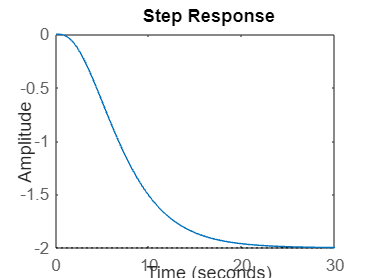

step(Wde)

T1 = 12;
T2 = 11;
T3 = 10;
Wp = tf(20, conv(conv([T1 1],[T2 1]),[T3 1]));
%Ap*(1+1/(Ti*s)+(Td*s)/(Tc*s+1))
%(Ap/Ti)*(Ti*s*(Tc*s+1) + (Tc*s+1) + Td*Ti*s^2)/(s*(Tc*s+1))
%(Ap/Ti)*(Ti*Tc*s^2 + Ti*s + Tc*s + 1 + Td*Ti*s^2)/(s*(Tc*s+1))
%(Ap/Ti)*(Ti*(Td+Tc)*s^2 + (Ti + Tc)*s + 1)/(s*(Tc*s+1))

%(T1*s + 1)*(T2*s + 1) = T1*T2*s^2 + (T1 + T2)*s + 1
%Ti*(Td+Tc) = T1*T2
%Ti+Tc = T1+T2
%Td/Tc = N -> Td = N*Tc
%Ti*(N+1)*Tc = T1*T2 -> Ti = T1*T2/((N+1)*Tc)
%T1+T2 = Tc + T1*T2/((N+1)*Tc)
%(N+1)*Tc^2 - (T1+T2)*(N+1)*Tc + T1*T2 = 0
N = 10;
root = roots([(N+1) -(T1+T2)*(N+1) T1*T2])

root =    22.4659
    0.5341



if root(2) < 0 || (root(2) > 0 && root(1) < root(2))
    Tc = root(1);
else
    Tc = root(2);
end

Td = N*Tc;
Ti = T1+T2-Tc;
Ap = 0.08;

Wc = (Ap/Ti)*tf([Ti*(Td+Tc) (Ti+Tc) 1],[Tc 1 0]);

Wo = minreal(Wc*Wp)

Wo =
 
           0.01333
  --------------------------
  s^3 + 1.972 s^2 + 0.1872 s
 
Continuous-time transfer function.
Model Properties


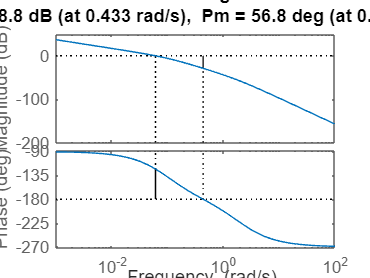

margin(Wo)

[Gm Pm wcg wcp] = margin(Wo)

Gm = 27.6913

Pm = 56.8326

wcg = 0.4327

wcp = 0.0608

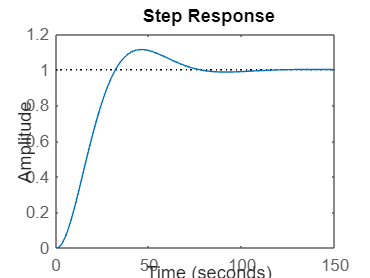


W = feedback(Wo, 1, -1);

step(W)

stepinfo(W)

ans = struct with fields:
         RiseTime: 21.1903
    TransientTime: 70.2710
     SettlingTime: 70.2710
      SettlingMin: 0.9074
      SettlingMax: 1.1134
        Overshoot: 11.3375
       Undershoot: 0
             Peak: 1.1134
         PeakTime: 46.0523


e = 1-dcgain(W)

e = 0


Ts = 1.5;
Wd = c2d(W, Ts, 'zoh')

Wd =
 
  0.004044 z^2 + 0.008975 z + 0.0009614
  -------------------------------------
  z^3 - 1.911 z^2 + 0.9769 z - 0.05191
 
Sample time: 1.5 seconds
Discrete-time transfer function.
Model Properties


%2*pd/wcg -> Ts
% wcg*Ts/2
pd = -rad2deg(wcg*Ts/2)

pd = -18.5932

% x1, x2
% x1' = x2
% m*x2' + b*x2 + k*x1 = u
% x2' = -k/m * x1 -b/m * x2 + 1/m * u
m = 100;
k = 1;
b = 2;
A = [0 1 ; -k/m -b/m];
B = [0 ; 1/m];
C = [1 0];
D = [0];

W = ss(A,B,C,D)

W =
 
  A = 
          x1     x2
   x1      0      1
   x2  -0.01  -0.02
 
  B = 
         u1
   x1     0
   x2  0.01
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties



eigen_O = eig(W)

eigen_O =   -0.0100 + 0.0995i
  -0.0100 - 0.0995i


det(ctrb(A,B))

ans = -1.0000e-04

det(obsv(A,C))

ans = 1


% 20 sec (5*T) -> T = 4 sec -> sc = -1/T
sc1 = -1/4;
sc2 = 5*sc1;

K = acker(A, B, [sc1, sc2]);
Mxu = [A B ; C D]\[0 ; 0 ; 1];
Mx = Mxu(1:2);
Mu = Mxu(3);

so1 = 10*sc1;
so2 = 10*sc2;

G = acker(A', C', [so1, so2])';

Ah = [A B ; 0 0 0];
Bh = [B ; 0];
Ch = [C 0];
Dh = [0];

det(obsv(Ah,Ch))

ans = 0.0100


soh1 = so1;
soh2 = so2;
soh3 = soh2;

Gh = acker(Ah', Ch', [soh1, soh2, soh3])';

Gh = 1.0e+04 *

    0.0027
    0.0218
    3.9062
